A = [0 1; -1 -1];
b = [0;5];
C = [1 0];
tn = 1.2;
sigma = 0;

rank([b A*b])

ans = 2

rank([C*b C*A*b])

ans = 1

rank([C;C*A])

ans = 2

rank([C*b;C*A*b])

ans = 1

Ad = [0 1; -15.6684 -7.9167];
H = [1 0];

eig(Ad)

ans =    -3.9467
   -3.9700


M = sylvester(A, -Ad, b*H);
K = H*M^-1

K =     2.9337    1.3833


A0g = [0 1 0 0; 0 0 1 0; 0 0 0 1; -625 -500 -150 -20];
eig(A0g)

ans =   -5.0006 + 0.0006i
  -5.0006 - 0.0006i
  -4.9994 + 0.0006i
  -4.9994 - 0.0006i


b0g = [0;0;0;1];
AM = A - b*K

AM =          0    1.0000
  -15.6684   -7.9167


eig(AM)

ans =    -3.9467
   -3.9700


syms s
C*inv(s*eye(2)-AM)*b

$$ans = \frac{50000}{10000\,s^{2}+79167\,s+156684}$$

gamma = 100000;
Tmdl = 10000;

th = [1 2];

warning off
SimNew = sim('assignment_model.slx','ReturnWorkspaceOutputs', 'on');

Simulation aborted

warning on

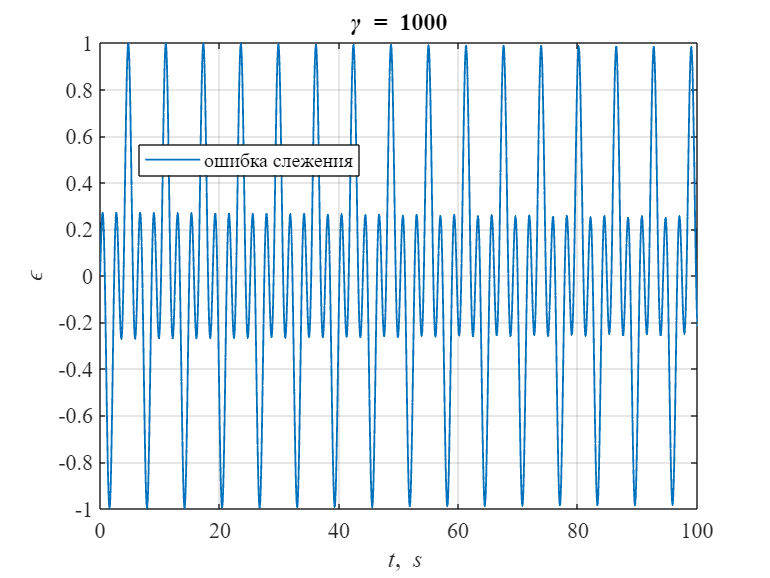

t = SimNew.out.time';
eps = squeeze(SimNew.out.signals(1).values);
u = squeeze(SimNew.out.signals(2).values);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,eps,'LineWidth',1)
hold on
grid on
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\epsilon')
legend('ошибка слежения','Location','best')
title('\gamma = 1000')

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,u,'LineWidth',1)
hold on
grid on
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\epsilon')
legend('управление','Location','best')
title('\gamma = 1000')

gamma = 10;
Tmdl = 1000;

warning off
SimNew = sim('model_2022b1.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.out.time;
eps = SimNew.out.signals(1).values;
u = SimNew.out.signals(2).values;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,eps,'LineWidth',1)
hold on
grid on
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\epsilon')
legend('ошибка слежения','Location','best')
title('\gamma = 10')

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,u,'LineWidth',1)
hold on
grid on
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\epsilon')
legend('управление','Location','best')
title('\gamma = 10')

ans = 2

ans = 1

ans = 2

ans = 1

K =     3.3337    1.7833


ans =   -5.0006 + 0.0006i
  -5.0006 - 0.0006i
  -4.9994 + 0.0006i
  -4.9994 - 0.0006i


AM =          0    1.0000
  -15.6684   -7.9167


ans =    -3.9467
   -3.9700
